# disadNB-IoT simulation

## transmission

clear
%base message
dataLength=12*21*2;
messageBits= randi([0 1],dataLength,1)

messageBits =      1
     0
     1
     0
     0
     1
     0
     1
     0
     0


% messageBits=ones(dataLength,1)
%map bits to qpsk symbols
messageInts=bit2int(messageBits,2)% grouped by 2 bits, converted to dec

messageInts =      2
     2
     1
     1
     0
     3
     3
     3
     2
     1


symbolMap=[1+1i, -1+1i, 1-1i, -1-1i] / sqrt(2); %normalized QPSK constellation points
messageSymbols = zeros(size(messageInts, 1), 1);
for k = 1:size(messageInts, 1)
    idx = messageInts(k) + 1; %map index
    messageSymbols(k) = symbolMap(idx); %symbolmap
end
messageSymbols

messageSymbols =    0.7071 - 0.7071i
   0.7071 - 0.7071i
  -0.7071 + 0.7071i
  -0.7071 + 0.7071i
   0.7071 + 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i
  -0.7071 - 0.7071i
   0.7071 - 0.7071i
  -0.7071 + 0.7071i


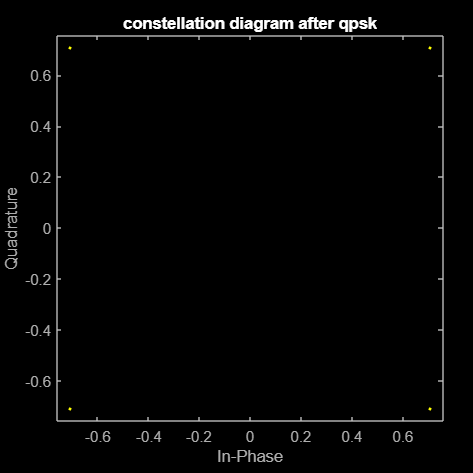

%plot scatterplot
figure;
scatterplot(messageSymbols);
title('constellation diagram after qpsk');

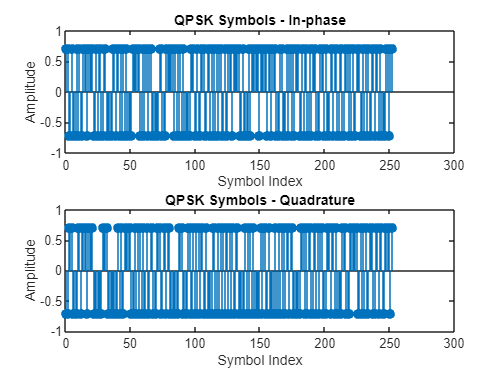


%plot time domain
figure;
subplot(2,1,1);
stem(real(messageSymbols), 'filled');
title('QPSK Symbols - In-phase');
xlabel('Symbol Index');
ylabel('Amplitude');
subplot(2,1,2);
stem(imag(messageSymbols), 'filled');
title('QPSK Symbols - Quadrature');
xlabel('Symbol Index');
ylabel('Amplitude');

% %ofdm
% % PARALLEL TO SERIAL STAP LOOPT FOUT
% numSC=12;% # subcarriers
% cpLen=3;%cyclic prefix length
% numSym=7;% # ofdm symbols
% bandwidth=180e3;
% SCS=15e3;
% carrierFreq=890e6;
% 
% numSymbolsRequired = numSC * numSym;
% if length(messageSymbols) < numSymbolsRequired
%     error('Not enough symbols to fill the OFDM frame');
% end
% 
% ofdmSymbolsMatrix = reshape(messageSymbols(1:numSymbolsRequired), numSC, numSym);%reshape into 12 carrier x7 symbols frame in freq domain
% 
% timeDomainSymbols = ifft(ofdmSymbolsMatrix, numSC);%time domain frame, 12 samples
% 
% cpSymbols = [timeDomainSymbols(end-cpLen+1:end, :); timeDomainSymbols];
% 
% txSignalOFDMA = cpSymbols(:);% (:) reshapes matrix into column
% 
% 
% 
% figure
% scatterplot(txSignalOFDMA)
% title('constellation diagram after OFDM');
% 
% % Plot the time domain signal
% figure;
% subplot(2,1,1);
% plot(real(txSignalOFDMA));
% title('OFDM Signal Time Domain');
% xlabel('Sample Index');
% ylabel('Amplitude');
% 
% [pxx,f] = pspectrum(txSignalOFDMA);
% subplot(2,1,2);
% plot(f,pow2db(pxx))
% grid on
% title('OFDM Signal Freq Domain');
% xlabel('Frequency (Hz)')
% ylabel('Power Spectrum (dB)')


numSC=12;% # subcarriers
numSym=21;% # ofdm symbols
SCS=15e3;
BW=SCS*numSC;
samplingRate = numSC * SCS;
symbolDuration = 1 / SCS; % Duration of one OFDM symbol (T=1/FS = 1/SCS)
SPS = round(samplingRate * symbolDuration);
t = (0:SPS-1) / samplingRate; %time vector
ofdmSignal = zeros(1, numSym * SPS);

cpLen=round(SPS/4);


ofdmMatrix = zeros(numSC,numSym);%12x7
for symbolIdx =1:numSym
    ofdmMatrix(:,symbolIdx)=messageSymbols((symbolIdx-1)*numSC+1:numSC*symbolIdx);
end
ofdmMatrix%every column represents 12 carriers for 1 ofdm symbol

ofdmMatrix =    0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 + 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i
   0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i
  -0.7071 + 0.7071i   0.7071 + 0.7071i   0.7071 - 0.7071i  -0.7071 - 0.7071i  -0.7071 - 0.7071i   0.7071 + 0.7071i  -0.7071 - 0.7071i   0.7071 - 0.7071i   0.7071 + 0.7071i   0.7071 - 0.70

%the entire column/symbol is transmitted at once at different freq

timeDomainSymbolMatrix = ifft(ofdmMatrix, numSC);%time domain frame, 12 samples per symbol
%every colum contains the sample of the symbol over time, the column
%elements are transmitted one by one
cp=timeDomainSymbolMatrix(end-(cpLen-1):end,:)

cp =    0.2357 - 0.2357i  -0.1179 + 0.1179i  -0.2357 - 0.2357i   0.1179 - 0.1179i   0.2357 + 0.3536i   0.0000 - 0.5893i  -0.2357 - 0.1179i  -0.1179 + 0.0000i   0.1179 - 0.3536i   0.0000 + 0.0000i  -0.4714 + 0.1179i   0.2357 - 0.1179i   0.1179 + 0.1179i   0.2357 - 0.1179i  -0.1179 - 0.1179i  -0.1179 + 0.0000i   0.3536 - 0.1179i   0.4714 + 0.1179i  -0.1179 - 0.1179i  -0.1179 - 0.1179i  -0.2357 + 0.2357i
  -0.1021 - 0.4125i   0.4240 - 0.0273i   0.0747 + 0.0747i  -0.3062 - 0.0589i   0.0589 + 0.3378i  -0.2041 + 0.1179i   0.1768 + 0.0158i  -0.2904 - 0.1179i   0.0431 - 0.2788i  -0.2041 + 0.2357i   0.0589 + 0.1021i   0.0589 + 0.2199i  -0.0158 - 0.1452i  -0.2199 + 0.2630i  -0.1179 + 0.3220i   0.0863 + 0.2041i  -0.1294 + 0.0431i  -0.0431 - 0.2788i  -0.2199 + 0.0589i   0.0863 + 0.1179i   0.2630 - 0.1021i
   0.2630 + 0.1021i   0.0589 - 0.2199i   0.0431 - 0.6008i  -0.1336 - 0.0905i  -0.4556 + 0.0589i   0.0000 - 0.3220i   0.0589 + 0.1021i   0.1179 - 0.2041i   0.1610 - 0.0747i  -0.0316 + 0.0000i   0.

timeDomainSymbolMatrix=[cp; timeDomainSymbolMatrix]%add cp

timeDomainSymbolMatrix =    0.2357 - 0.2357i  -0.1179 + 0.1179i  -0.2357 - 0.2357i   0.1179 - 0.1179i   0.2357 + 0.3536i   0.0000 - 0.5893i  -0.2357 - 0.1179i  -0.1179 + 0.0000i   0.1179 - 0.3536i   0.0000 + 0.0000i  -0.4714 + 0.1179i   0.2357 - 0.1179i   0.1179 + 0.1179i   0.2357 - 0.1179i  -0.1179 - 0.1179i  -0.1179 + 0.0000i   0.3536 - 0.1179i   0.4714 + 0.1179i  -0.1179 - 0.1179i  -0.1179 - 0.1179i  -0.2357 + 0.2357i
  -0.1021 - 0.4125i   0.4240 - 0.0273i   0.0747 + 0.0747i  -0.3062 - 0.0589i   0.0589 + 0.3378i  -0.2041 + 0.1179i   0.1768 + 0.0158i  -0.2904 - 0.1179i   0.0431 - 0.2788i  -0.2041 + 0.2357i   0.0589 + 0.1021i   0.0589 + 0.2199i  -0.0158 - 0.1452i  -0.2199 + 0.2630i  -0.1179 + 0.3220i   0.0863 + 0.2041i  -0.1294 + 0.0431i  -0.0431 - 0.2788i  -0.2199 + 0.0589i   0.0863 + 0.1179i   0.2630 - 0.1021i
   0.2630 + 0.1021i   0.0589 - 0.2199i   0.0431 - 0.6008i  -0.1336 - 0.0905i  -0.4556 + 0.0589i   0.0000 - 0.3220i   0.0589 + 0.1021i   0.1179 - 0.2041i   0.1610 - 0.0747i  -0


timeDomainSymbols=reshape (timeDomainSymbolMatrix,[],1)

timeDomainSymbols =    0.2357 - 0.2357i
  -0.1021 - 0.4125i
   0.2630 + 0.1021i
  -0.1179 - 0.1179i
   0.0589 + 0.0158i
   0.1021 - 0.4125i
   0.2357 + 0.0000i
  -0.2199 + 0.2630i
   0.0589 + 0.2199i
   0.3536 + 0.1179i


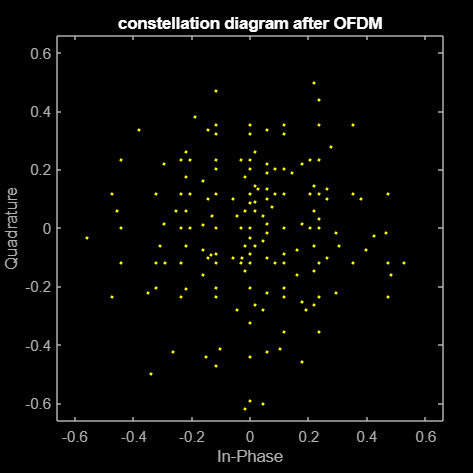

% plot ofdm signal

figure
scatterplot(timeDomainSymbols)
title('constellation diagram after OFDM');

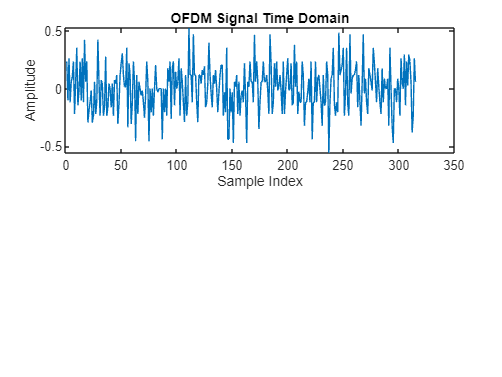


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(timeDomainSymbols));
title('OFDM Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

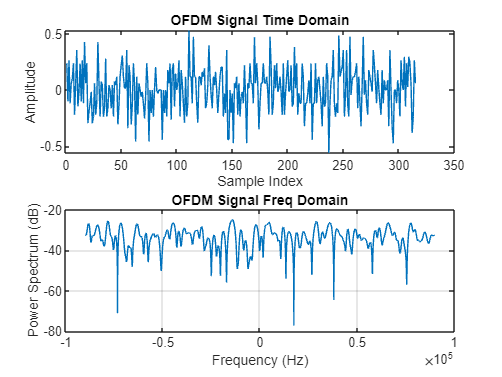


[pxx,f] = pspectrum(timeDomainSymbols,samplingRate);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('OFDM Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

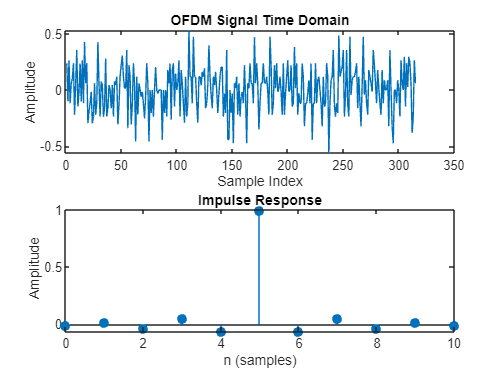

%upsampling
L = 1;  % Upsampling factor
rolloff = 0.25;  % Roll-off factor for the RRC filter
span = 10;  % Filter span in symbols

txSignalUpsampled = upsample(timeDomainSymbols, L);

rrcFilter = rcosdesign(rolloff, span, L);
impz(rrcFilter)

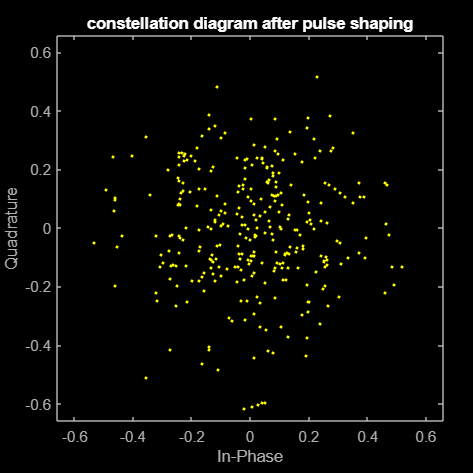


txSignalShaped = conv(txSignalUpsampled, rrcFilter, 'same');

figure
scatterplot(txSignalShaped)
title('constellation diagram after pulse shaping');

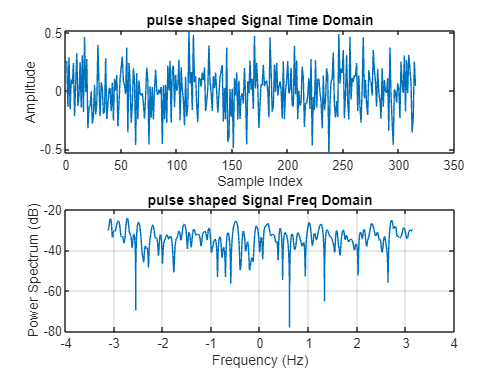


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(txSignalShaped));
title('pulse shaped Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

[pxx,f] = pspectrum(txSignalShaped);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('pulse shaped Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

% %convert to 900 MHz
% Fc=900e6;
% Fs=2*180e3;
% t = (0:length(txSignalShaped)-1)' / Fs; % Time vector
% cosCarrier = cos(2 * pi * Fc * t);
% sinCarrier = sin(2 * pi * Fc * t);
% txPassband = real(txSignalShaped) .* cosCarrier - imag(txSignalShaped) .* sinCarrier;
% % Plot the time domain signal after upconversion
% figure;
% plot(t(1:length(txPassband)), txPassband); % Plot a segment for better visualization
% title('Passband Signal - Time Domain');
% xlabel('Time (s)');
% ylabel('Amplitude');
% %freq
% [pxx,f] = pspectrum(txSignalShaped,Fs);
% subplot(2,1,2);
% plot(f+Fc,pow2db(pxx))
% grid on
% title('pulse shaped Signal Freq Domain');
% xlabel('Frequency (Hz)')
% ylabel('Power Spectrum (dB)')

## channel

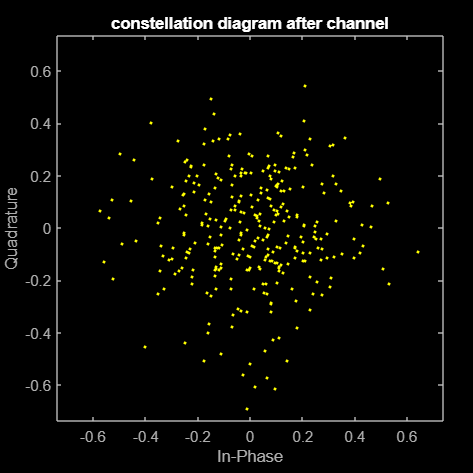

SNR=25;%check filters, error rate is te hoog
rxSignal=awgn(txSignalShaped,SNR);

% rxSignal=awgn(txSignalUpsampled,SNR);
% rxSignal=txSignalShaped;

% Plot the time domain signal after channel
figure
scatterplot(rxSignal)
title('constellation diagram after channel');

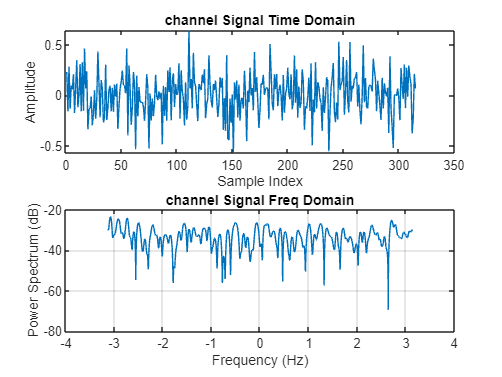


% Plot the time domain signal
figure;
subplot(2,1,1);
plot(real(rxSignal));
title('channel Signal Time Domain');
xlabel('Sample Index');
ylabel('Amplitude');

[pxx,f] = pspectrum(rxSignal);
subplot(2,1,2);
plot(f,pow2db(pxx))
grid on
title('channel Signal Freq Domain');
xlabel('Frequency (Hz)')
ylabel('Power Spectrum (dB)')

## receiver

% %downconvert to baseband
% I_component = rxSignal .* cosCarrier;
% Q_component = rxSignal .* sinCarrier;
% 
% filterOrder = 64;
% cutoffFreq = Fc / (2 * Fs); % Normalized cutoff frequency
% lpFilt = designfilt('lowpassfir', 'FilterOrder', filterOrder, 'CutoffFrequency', 0.5);
% 
% I_baseband = filtfilt(lpFilt, I_component);
% Q_baseband = filtfilt(lpFilt, Q_component);
% 
% rxBaseband = I_baseband - 1i * Q_baseband;

%matched filter
matchedFilter = rcosdesign(rolloff, span, L);
rxSignalFiltered = conv(rxSignal, matchedFilter, 'same');
rxSignalFiltered

rxSignalFiltered =    0.2578 - 0.1446i
  -0.2015 - 0.4122i
   0.3189 + 0.1749i
  -0.1801 - 0.2241i
   0.1411 + 0.1019i
   0.0136 - 0.4796i
   0.2191 + 0.0419i
  -0.1787 + 0.2835i
   0.0704 + 0.2641i
   0.3169 + 0.1270i


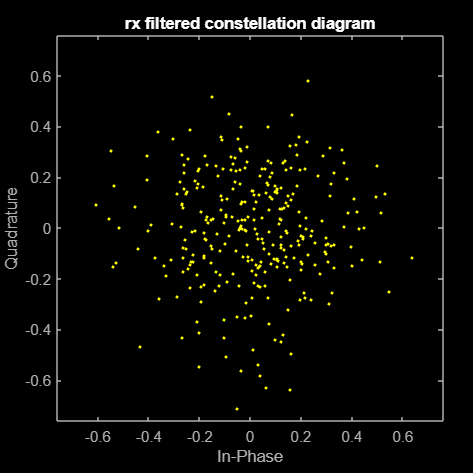


%downsample
% rxSignalDownsampled = downsample(rxSignalFiltered, L);

figure;
scatterplot(rxSignalFiltered);
title('rx filtered constellation diagram');


%cp
rxSymbolsWithCP = reshape(rxSignalFiltered, [], numSym);
% rxSymbolsWithCP = reshape(rxSignal, [], numSym);
rxSymbolsWithCP

rxSymbolsWithCP =    0.2578 - 0.1446i  -0.2278 - 0.0126i  -0.2074 - 0.1841i   0.1407 - 0.0083i   0.1824 + 0.3302i   0.0637 - 0.6298i  -0.3086 + 0.0189i   0.0171 + 0.0760i   0.0727 - 0.2755i  -0.0449 - 0.0047i  -0.6076 + 0.0920i   0.3075 - 0.1309i   0.0374 + 0.1317i   0.2271 - 0.1054i  -0.1483 - 0.0810i  -0.1694 + 0.0462i   0.2962 - 0.0928i   0.5302 + 0.1375i  -0.1372 - 0.2454i  -0.1516 - 0.0681i  -0.2455 + 0.2738i
  -0.2015 - 0.4122i   0.5154 + 0.0609i   0.1516 + 0.0880i  -0.3370 - 0.1462i   0.1566 + 0.3236i  -0.2753 + 0.1839i   0.2991 - 0.0360i  -0.3126 - 0.1259i   0.0400 - 0.2295i  -0.1861 + 0.1635i   0.1937 + 0.0658i  -0.0597 + 0.2793i   0.0950 - 0.1209i  -0.2022 + 0.2343i  -0.0469 + 0.3506i   0.1491 + 0.1262i  -0.1475 + 0.0355i  -0.1028 - 0.3616i  -0.1077 + 0.2361i   0.1252 + 0.0762i   0.2560 - 0.0563i
   0.3189 + 0.1749i  -0.0148 - 0.2922i   0.0387 - 0.5800i  -0.0833 - 0.0291i  -0.5564 + 0.0385i   0.0029 - 0.3468i  -0.0316 + 0.1037i   0.1350 - 0.1352i   0.2071 - 0.0418i  -0.1036 +

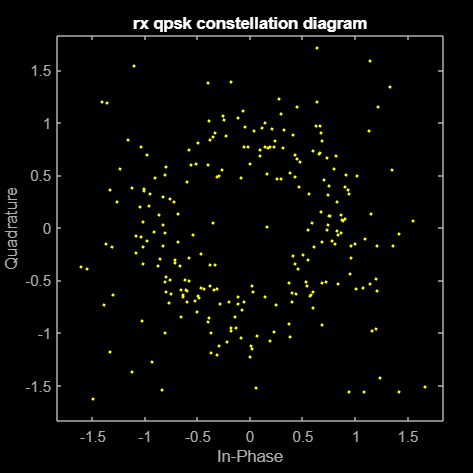

rxSymbols = rxSymbolsWithCP(cpLen+2:end, :);%remove cp from top of matrix (cplen +2 because matlab takes from the next sample to the end)
%fft
rxSymbolsFreq = fft(rxSymbols, numSC);% fft to freq domain
%qpsk
rxQPSKSymbols = rxSymbolsFreq(:);
demodulatedBits = zeros(length(rxQPSKSymbols)*2, 1);
figure;
scatterplot(rxQPSKSymbols);
title('rx qpsk constellation diagram');

% Demodulate QPSK symbols to bits
for k = 1:length(rxQPSKSymbols)
    [~, idx] = min(abs(rxQPSKSymbols(k) - symbolMap));
    demodulatedBits(2*k-1:2*k) = de2bi(idx-1, 2, 'left-msb');
end

errors=sum(demodulatedBits'~=messageBits(1:dataLength)')

errors = 261

nbiot_ber=errors/dataLength

nbiot_ber = 0.5179


symbolRate=samplingRate/SPS

symbolRate = 15000

bitRate =  2*12*symbolRate

bitRate = 360000

EbN0_sim=SNR*samplingRate/bitRate

EbN0_sim = 12.5000


SNR_linear = 10^(SNR / 10);
Eb_N0 = (SNR_linear * samplingRate) / bitRate

Eb_N0 = 158.1139

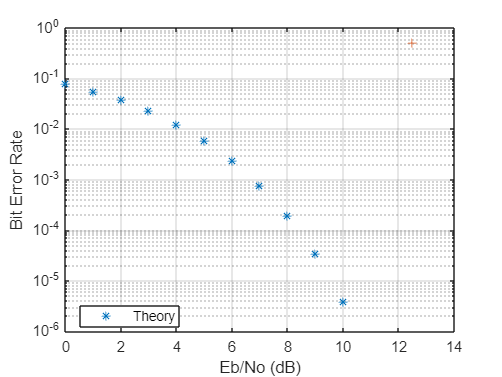

%ber
%https://nl.mathworks.com/help/releases/R2023a/comm/ug/analytical-expressions-used-in-berawgn-function-and-bit-error-rate-analysis-app.html
EbN0=(0:10);
ber=berawgn(EbN0,"psk",4,"nondiff");
figure
semilogy(EbN0',ber,'*')
hold on
semilogy(EbN0_sim',nbiot_ber,'+')

legend('Theory','Location','Best')
xlabel('Eb/No (dB)')
ylabel('Bit Error Rate')
grid on